% mikexcohen.com

## create a Morlet wavelet

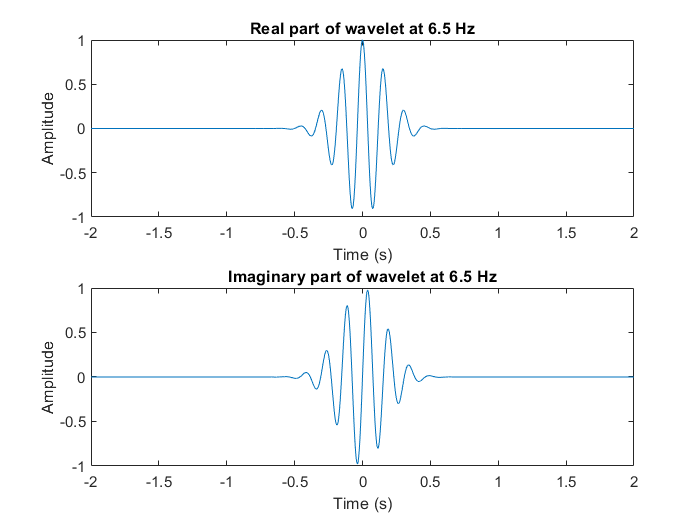

srate = 1000; % in hz
time  = -2:1/srate:2; % best practice is to have time=0 at the center of the wavelet
frex  = 6.5; % frequency of wavelet, in Hz

% create complex sine wave
sine_wave = exp( 1i*2*pi*frex.*time );

% create Gaussian window
s = 7 / (2*pi*frex); % this is the standard deviation of the gaussian
gaus_win  = exp( (-time.^2) ./ (2*s^2) );


% now create Morlet wavelet
cmw = sine_wave .* gaus_win;


figure(1), clf

subplot(211)
plot(time,real(cmw))
xlabel('Time (s)'), ylabel('Amplitude')
title([ 'Real part of wavelet at ' num2str(frex) ' Hz' ])

subplot(212)
plot(time,imag(cmw))
xlabel('Time (s)'), ylabel('Amplitude')
title([ 'Imaginary part of wavelet at ' num2str(frex) ' Hz' ])

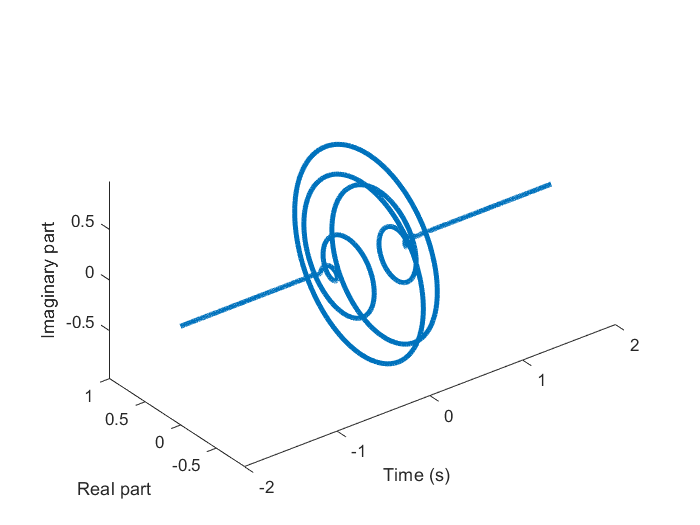



figure(2), clf
plot3(time,real(cmw),imag(cmw),'linew',3)
axis image
xlabel('Time (s)'), ylabel('Real part'), zlabel('Imaginary part')

rotate3d

## Morlet wavelet in the frequency domain

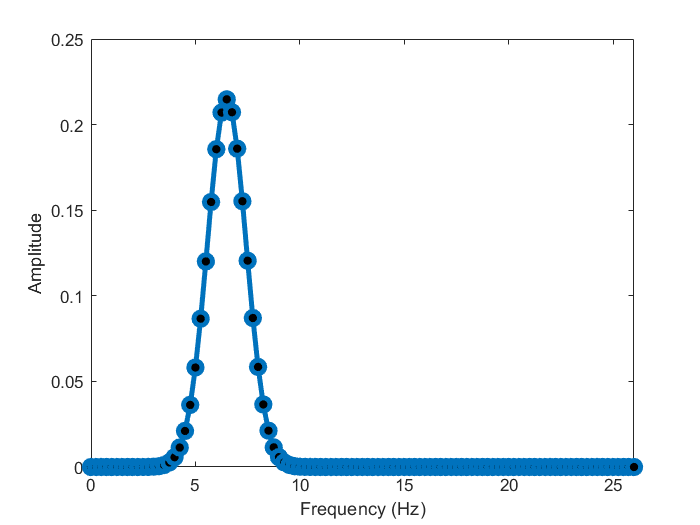

cmwX = fft(cmw)/length(cmw);

hz = linspace(0,srate/2,floor(length(cmw)/2)+1);

figure(3), clf
plot(hz,2*abs(cmwX(1:length(hz))),'o-','linew',3,'markerface','k','markersize',8)
xlabel('Frequency (Hz)'), ylabel('Amplitude')
set(gca,'xlim',[0 frex*4])